% openExample('daq/CharacterizeLEDwADALM1000Example')
% openExample('daq/EstimateTransferFunctionwADALM1000Example')

dev = daqlist;

Unable to detect 'ni' hardware:
National Instruments NI-DAQmx driver is either not installed or the installed version is not supported.
Use the Windows Control Panel to uninstall any existing NI-DAQmx driver listed under 'National Instruments Software'.
Then, open the Add-On Explorer to install the Data Acquisition Toolbox Support Package for 
National Instruments NI-DAQmx Devices.



dev{1,"DeviceInfo"};
d = daq("adi");

addoutput(d,"SMU1","A","Voltage")
% addinput(d,"SMU1","A","Current")
addinput(d,"SMU1","B","Voltage")

d.Channels

ans =     Index    Type    Device    Channel      Measurement Type             Range            Name  
    _____    ____    ______    _______    _____________________    _________________    ________

      1      "ao"    "SMU1"      "A"      "Voltage (SingleEnd)"    "0 to +5.0 Volts"    "SMU1_A"
      2      "ai"    "SMU1"      "B"      "Voltage (SingleEnd)"    "0 to +5.0 Volts"    "SMU1_B"


write(d,5);
pause(1);
write(d,0);
read(d)

ans = 1×1 timetable
    Time    SMU1_B
    ____    ______

    0 秒    0.3727


sensorData = read(d)

sensorData = 1×1 timetable
    Time    SMU1_B 
    ____    _______

    0 秒    0.37285


while true
    sensorData = read(d);
    if sensorData.SMU1_B > 1
        write(d,5);
        pause(5);
        write(d,0);
        break
    end
end

% 声あり 4.8
% 声なし 0.37

v = linspace(0,5,250)';
i = readwrite(d,v,"OutputFormat","Matrix");

normErr = -1;
errThreshold = 0.001;
numPointForLine = numel(v) - 10;
% while 

% d.Channels

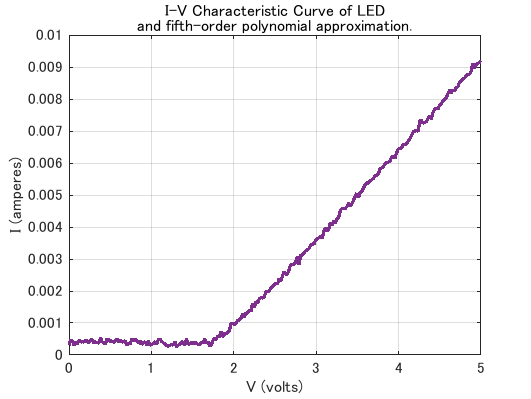

% % Plot the measured data.
plot(v,i,'LineWidth',2);
hold on;
grid on;
ylabel('I (amperes)');
xlabel('V (volts)');
title({'I-V Characteristic Curve of LED';'and fifth-order polynomial approximation.'});

write(d,0);
close
clear d